# Power Spectral Density Analysis

- Get the power spectral of each sample pair (i.e sick & normal)

- Sum the spectra of each class's (i.e sick & normal) channel across subjects. Also get the vector of the total power in all the channels (i.e sum all the channels)

- Plot the spectra of the relative power in each channel

- Plot the average power of each channel when summed across samples

- Plot average power of each class by using the previous results

For this code you need to change the directories of your trial to traget the right **dataset** and **sample extraction method**. In this case there are two datasets:-

- **Kfold_roi**: which includes ERP epoches

- **Kfold_pruned**: Epoches from continues EEG data

There are also two extraction methods:-

- Activation Maximization

- Sorting

# This is for sorted sample method

clear;
load('C:\Users\Abdulsatar\Documents\UBICOMP\Thesis Work\ReverseNeuro\Results\Plots\trial21\Kfold_roi\trial 4\sorting\matrix_jitter_output.mat');
srate = 250;
nfft = srate;
f_length = (nfft/2) + 1;
sample_no = 29;
window_length = srate; % Size of the segments make to calculate PSD
overlap_length = 0; % Placing a 40% overlap between the segments
f = (0:1:40); % Frequencies of interest
f_channels = [4, 5, 6, 7, 8] - 3; % Frontal channels
c_channels = [9, 10, 11, 12, 13] - 3; % Central channels
p_channels =  [14, 15, 16] - 3; % Parietal channels
o_channels = [17, 18, 19] - 3; % Occipital channels

c_regions = {f_channels, c_channels, p_channels, o_channels};

% ARRAY TO HOLD SAMPLES
true_sick_array = []; % 16x250xM here M is the number of samples 
true_normal_array = []; % 16x250xM here M is the number of samples 
false_sick_array = []; % 16x250xM here M is the number of samples 
false_normal_array = []; % 16x250xM here M is the number of samples 

for i = (1:sample_no)
    fieldName = ['field', num2str(i)];

    % GET THE SAMPLES
    % Get the best sick and normal samples
    true_sick_sample = export_matlab.(fieldName).true_sick;
    true_normal_sample = export_matlab.(fieldName).true_normal;

    % Get the worst sick and normal samples
    false_sick_sample = export_matlab.(fieldName).false_sick;
    false_normal_sample = export_matlab.(fieldName).false_normal;

    % GET THE SPECTRAS
    % Get the best spectra and their respective frequncies for both classes
    if ~isempty(true_sick_sample)
      if ~isempty(true_sick_array)
          true_sick_array = cat(3, true_sick_array, true_sick_sample);
      else
          true_sick_array = true_sick_sample;
      end
    end
    if ~isempty(true_normal_sample)
      if ~isempty(true_normal_array)
          true_normal_array = cat(3, true_normal_array, true_normal_sample);
      else
          true_normal_array = true_normal_sample;
      end
    end

    % Get the worst spectra and their respective frequncies for both classes
    if ~isempty(false_sick_sample)
      if ~isempty(false_sick_array)
          false_sick_array = cat(3, false_sick_array, false_sick_sample);
      else
          false_sick_array = false_sick_sample;
      end
    end
    if ~isempty(false_normal_sample)
      if ~isempty(false_normal_array)
          false_normal_array = cat(3, false_normal_array, false_normal_sample);
      else
          false_normal_array = false_normal_sample;
      end
    end
end

% REGIONAL DATA
true_sick_region_array = zeros(length(c_regions), srate);  
true_normal_region_array = zeros(length(c_regions), srate); 
false_sick_region_array = zeros(length(c_regions), srate);  
false_normal_region_array = zeros(length(c_regions), srate); 

region_cases = {true_sick_region_array, true_normal_region_array, false_sick_region_array, false_normal_region_array};
channel_cases = {true_sick_array, true_normal_array, false_sick_array, false_normal_array};

for case_id = (1:length(region_cases))
    for region_id = (1:length(c_regions))
        p_sample_no = size(channel_cases{case_id}(c_regions{region_id},:,:),3);
        s_placeholder = sum(channel_cases{case_id}(c_regions{region_id},:,:),3) / p_sample_no; % across samples
        c_placeholder = sum(s_placeholder,1) / size(s_placeholder,1); % across regions
        region_cases{case_id}(region_id,:) = c_placeholder;
    end
end

% GET THE ABSOLUT SPECTRA
% best output spectras of the subjects

[sp, fq] = pwelch(region_cases{1}', window_length, overlap_length, nfft, srate);
t_s_absolute_spectra = sp';

[sp, fq] = pwelch(region_cases{2}', window_length, overlap_length, nfft, srate);
t_n_absolute_spectra = sp';


% worst output spectras of the subjects

[sp, fq] = pwelch(region_cases{3}', window_length, overlap_length, nfft, srate);
f_s_absolute_spectra = sp';

[sp, fq] = pwelch(region_cases{4}', window_length, overlap_length, nfft, srate);
f_n_absolute_spectra = sp';


% GET THE RELATIVE POWER
% Best samples

t_s_relative_power = t_s_absolute_spectra ./sum(t_s_absolute_spectra, 2); % The relative power of each channel compared to the total power
t_n_relative_power = t_n_absolute_spectra ./sum(t_n_absolute_spectra, 2); % The relative power of each channel compared to the total power

% Worst samples

f_s_relative_power = f_s_absolute_spectra ./sum(f_s_absolute_spectra, 2); % The relative power of each channel compared to the total power
f_n_relative_power = f_n_absolute_spectra ./sum(f_n_absolute_spectra, 2); % The relative power of each channel compared to the total power

labels = {'Frontal', 'Central', 'Parietal', 'Occipital'};

## Plot Relative Power Density Of Each Channel

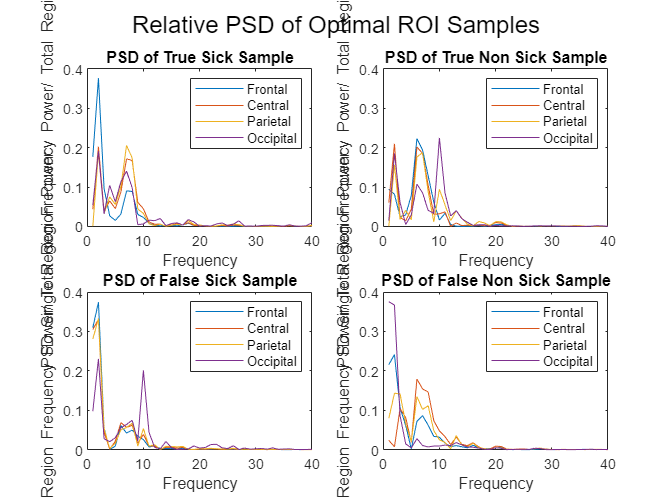

figure; % create a new figure

% Plot for matrix Sick
subplot(2,2,1); % Divide plot into 1 row, 1 columns, and select the first plot
for i = 1:size(t_s_relative_power, 1) % loop over rows
    plot(t_s_relative_power(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of True Sick Sample');
ylabel('PSD {Single Region Frequency Power/ Total Region Power}');
xlabel('Frequency');
ylim([0, 0.4]);
xlim([0, 40]);
legend(labels);

subplot(2,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(t_n_relative_power, 1) % loop over rows
    plot(t_n_relative_power(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of True Non Sick Sample');
ylabel('PSD {Single Region Frequency Power/ Total Region Power}');
xlabel('Frequency');
ylim([0, 0.4]);
xlim([0, 40]);
legend(labels);

subplot(2,2,3); % Divide plot into 2 row, 1 columns, and select the first plot
for i = 1:size(f_s_relative_power, 1) % loop over rows
    plot(f_s_relative_power(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of False Sick Sample');
ylabel('PSD {Single Region Frequency Power/ Total Region Power}');
xlabel('Frequency');
ylim([0, 0.4]);
xlim([0, 40]);
legend(labels);

subplot(2,2,4); % Divide plot into 2 row, 2 columns, and select the first plot
for i = 1:size(f_n_relative_power, 1) % loop over rows
    plot(f_n_relative_power(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of False Non Sick Sample');
ylabel('PSD {Single Region Frequency Power/ Total Region Power}');
xlabel('Frequency');
ylim([0, 0.4]);
xlim([0, 40]);
legend(labels);

sgtitle('Relative PSD of Optimal ROI Samples');

## Absolut Power Spectral Density of Each Region

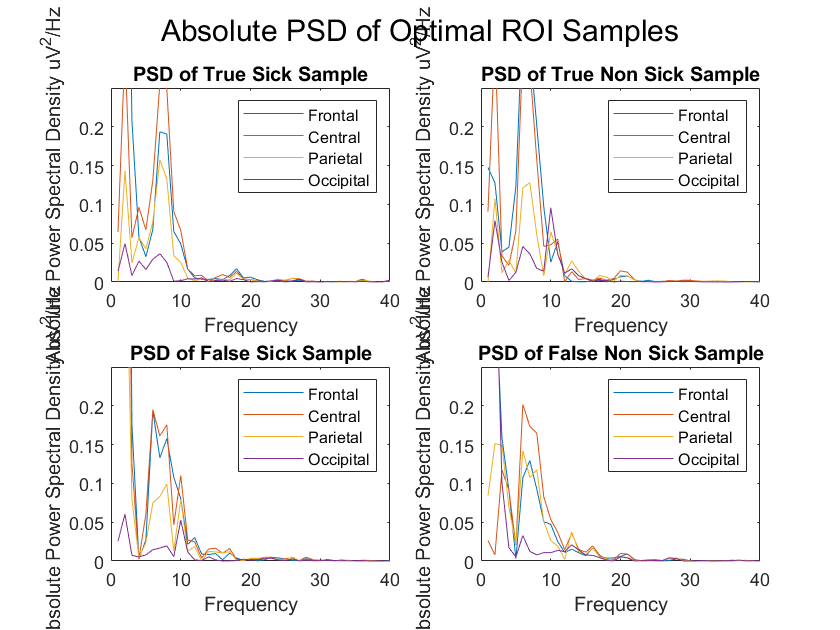

figure; % create a new figure

% Plot for matrix Sick
subplot(2,2,1); % Divide plot into 1 row, 1 columns, and select the first plot
for i = 1:size(t_s_absolute_spectra, 1) % loop over rows
    plot(t_s_absolute_spectra(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of True Sick Sample');
ylabel('Absolute Power Spectral Density uV^2/Hz');
xlabel('Frequency');
ylim([0, 0.25]);
xlim([0, 40]);
legend(labels);

subplot(2,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(t_n_absolute_spectra, 1) % loop over rows
    plot(t_n_absolute_spectra(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of True Non Sick Sample');
ylabel('Absolute Power Spectral Density uV^2/Hz');
xlabel('Frequency');
ylim([0, 0.25]);
xlim([0, 40]);
legend(labels);

subplot(2,2,3); % Divide plot into 2 row, 1 columns, and select the first plot
for i = 1:size(f_s_absolute_spectra, 1) % loop over rows
    plot(f_s_absolute_spectra(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of False Sick Sample');
ylabel('Absolute Power Spectral Density uV^2/Hz');
xlabel('Frequency');
ylim([0, 0.25]);
xlim([0, 40]);
legend(labels);

subplot(2,2,4); % Divide plot into 2 row, 2 columns, and select the first plot
for i = 1:size(f_n_absolute_spectra, 1) % loop over rows
    plot(f_n_absolute_spectra(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of False Non Sick Sample');
ylabel('Absolute Power Spectral Density uV^2/Hz');
xlabel('Frequency');
ylim([0, 0.25]);
xlim([0, 40]);
legend(labels);
sgtitle('Absolute PSD of Optimal ROI Samples');

# This is for maximization activation method


clear;
load('C:\Users\Abdulsatar\Documents\UBICOMP\Thesis Work\ReverseNeuro\Results\Plots\trial21\Kfold_roi\trial 3\maximization\matrix_jitter_output.mat');
srate = 250; % Sampling rate
nfft = srate;
f_length = (nfft/2) + 1;
sample_no = 29;
window_length = srate; % Size of the segments make to calculate PSD
overlap_length = 0; % Placing a 40% overlap between the segments
f = (0:1:40); % Frequencies of interest
s_sumed_spectra = zeros(16, f_length); % The sum of the channel spectral subjects (16 X 126) => (Channels X Frequencies)
n_sumed_spectra = zeros(16, f_length); % The sum of the channel spectral subjects (16 X 126) => (Channels X Frequencies)
f_channels = [4, 5, 6, 7, 8] - 3; % Frontal channels
c_channels = [9, 10, 11, 12, 13] - 3; % Central channels
p_channels =  [14, 15, 16] - 3; % Parietal channels
o_channels = [17, 18, 19] - 3; % Occipital channels

c_regions = {f_channels, c_channels, p_channels, o_channels};

sick_samples_array = []; % 16x250x4
normal_samples_array = []; % 16x250x4

for i = (1:sample_no)
    fieldName = ['field', num2str(i)];

    % Get the sick and normal samples
    sick_sample = export_matlab.(fieldName).sick;
    normal_sample = export_matlab.(fieldName).normal;

    sick_samples_array = cat(3, sick_samples_array, sick_sample);
    normal_samples_array = cat(3, normal_samples_array, normal_sample);
end

sick_region_signals = zeros(length(c_regions), srate);
normal_region_signals = zeros(length(c_regions), srate);

region_cases = {sick_region_signals, sick_region_signals};
channel_cases = {sick_samples_array, normal_samples_array};

for case_id = (1:length(region_cases))
    for region_id = (1:length(c_regions))
        p_sample_no = size(channel_cases{case_id}(c_regions{region_id},:,:),3);
        s_placeholder = sum(channel_cases{case_id}(c_regions{region_id},:,:),3) / p_sample_no; % across samples
        c_placeholder = sum(s_placeholder,1) / size(s_placeholder,1); % across regions
        region_cases{case_id}(region_id,:) = c_placeholder;
    end
end

% Get the ABSOLUTE spectra and their respective frequncies for both classes
[s_spectra, s_freqs] = pwelch(double(region_cases{1}'), window_length, overlap_length, nfft, srate);
[n_spectra, n_freqs] = pwelch(double(region_cases{2}'), window_length, overlap_length, nfft, srate);

s_absolute_spectra = s_spectra';
n_absolute_spectra = n_spectra';

s_relative_power = s_absolute_spectra ./sum(s_absolute_spectra, 2); % The relative power of each channel compared to the total power
n_relative_power = n_absolute_spectra ./sum(n_absolute_spectra, 2); % The relative power of each channel compared to the total power

labels = {'Frontal', 'Central', 'Parietal', 'Occipital'};

## Plot Relative Power Density Of Regions

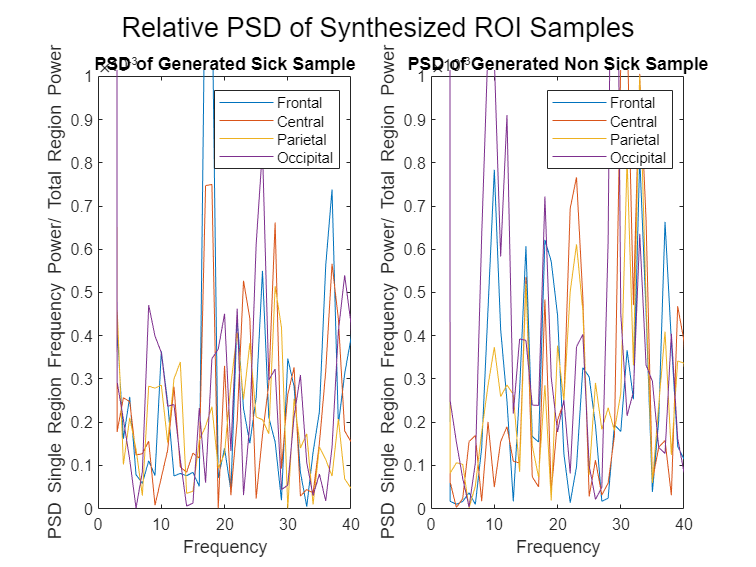

figure; % create a new figure

% Plot for matrix Sick
subplot(1,2,1); % Divide plot into 1 row, 2 columns, and select the first plot
for i = 1:size(s_relative_power, 1) % loop over rows
    plot(s_relative_power(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of Generated Sick Sample');
ylabel('PSD {Single Region Frequency Power/ Total Region Power}');
xlabel('Frequency');
ylim([0, 0.001]);
xlim([0, 40]);
legend(labels);

% Plot for matrix B
subplot(1,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(n_relative_power, 1) % loop over rows
    plot(n_relative_power(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of Generated Non Sick Sample');
ylabel('PSD {Single Region Frequency Power/ Total Region Power}');
xlabel('Frequency');
ylim([0, 0.001]);
xlim([0, 40]);
legend(labels);
sgtitle('Relative PSD of Synthesized ROI Samples');

## Absolute Power Spectral Density of Each Region

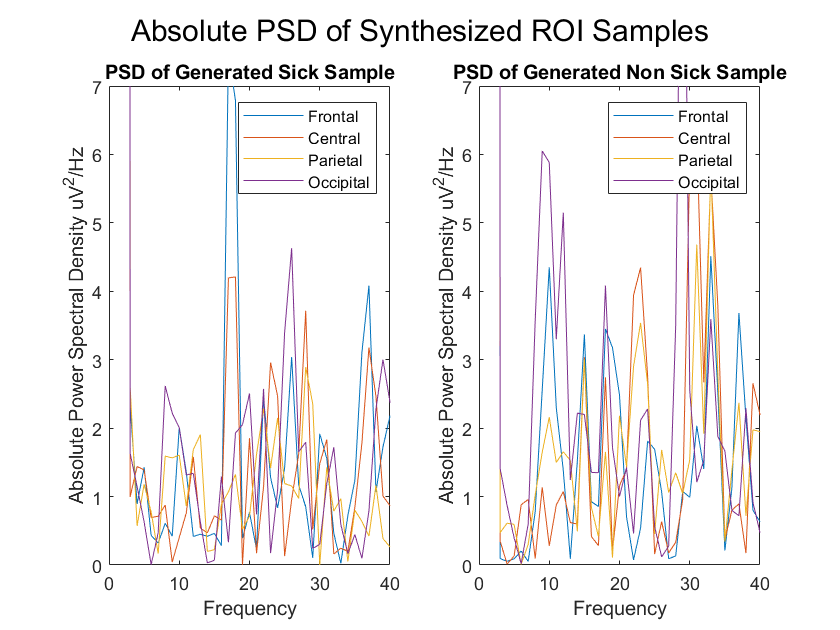

figure; % create a new figure

% Plot for matrix Sick
subplot(1,2,1); % Divide plot into 1 row, 2 columns, and select the first plot
for i = 1:size(s_absolute_spectra, 1) % loop over rows
    plot(s_absolute_spectra(i,:)); % plot each row on the same plot. Divide by the number of samples to get the average
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of Generated Sick Sample');
ylabel('Absolute Power Spectral Density uV^2/Hz');
xlabel('Frequency');
xlim([0, 40]);
ylim([0,7]);
legend(labels);

% Plot for matrix B
subplot(1,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(n_absolute_spectra, 1) % loop over rows
    plot(n_absolute_spectra(i,:)); % plot each row on the same plot. Divide by the number of samples to get the average
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of Generated Non Sick Sample');
ylabel('Absolute Power Spectral Density uV^2/Hz');
xlabel('Frequency');
xlim([0, 40]);
ylim([0,7]);
legend(labels);
sgtitle('Absolute PSD of Synthesized ROI Samples');